# Flux balance analysis on an aerobic and anaerobic normal GEM

*By: Michiel Adriaens, Maastricht Centre for Systems Biology, Maastricht University*

*Date: 18-06-2018*

## Introduction

In this interactive document, we will simulate the production of energy, i.e. ATP, under aerobic  and anaerobic conditions under normal situations. 

The procedure for each simulation is the same. For each new simulation, the original model will be copied to a new variable. This preserves the constraints of the original model to perform further simulations with new constraints. Additionally, this method of renaming the model avoids confusion while performing multiple simulations at the same time.

*Note: This script is in part based on the FBA tutorial from COBRA: *[goo.gl/SvSAoQ](http://goo.gl/SvSAoQ)

## Section 0: Some preliminaries

Before we start the analyses, there are a couple of things we need to take care of. 

First, we need to browse to the folder containing all the practical materials by clicking on the open folder icon ( ) on the topleft of the Matlab menubar. Next, we we load the required Recon 2.2 model with the following code:

load('recon22.mat');


Let's have a look at the GEM:

recon22

recon22 = struct with fields:
        modelVersion: [1×1 struct]
                rxns: {7785×1 cell}
                mets: {5324×1 cell}
                   S: [5324×7785 double]
                 rev: [7785×1 double]
                   c: [7785×1 double]
            metNames: {5324×1 cell}
         metFormulas: {5324×1 cell}
                  lb: [7785×1 double]
                  ub: [7785×1 double]
           metCharge: [5324×1 double]
               rules: {7785×1 cell}
               genes: {1675×1 cell}
          rxnGeneMat: [7785×1675 double]
             grRules: {7785×1 cell}
          subSystems: {7785×1 cell}
    confidenceScores: {7785×1 cell}
       rxnReferences: {7785×1 cell}
        rxnECNumbers: {7785×1 cell}
            rxnNotes: {7785×1 cell}
            rxnNames: {7785×1 cell}
          metChEBIID: {5324×1 cell}
             metHMDB: {5324×1 cell}
           metKEGGID: {5324×1 cell}
        metPubChemID: {5324×1 cell}
      metInChIString: {5324×1 cell}
               

We can see several important elements that are present in the object:

- *rxns *= all reactions contained in the model

- *mets *= metabolites

- *S *= the stoichiometric matrix 

- *genes * = genes

There are different solvers available to perform flux balance analysis. For this practical, we will simply stick to the default:

changeCobraSolver('glpk','all');

 > The solver compatibility is not tested with MATLAB R2019b.
 > Solver for LP problems has been set to glpk.
 > The solver compatibility is not tested with MATLAB R2019b.
 > Solver for MILP problems has been set to glpk.
 > Solver glpk not supported for problems of type MIQP. No solver set for this problemtype 
 > Solver glpk not supported for problems of type NLP. No solver set for this problemtype 
 > Solver glpk not supported for problems of type QP. Currently used: qpng 


## Section 1: Simulating cells growing in RPMI medium

Next, we will simulate cells growing in RPMI medium, but first:

- Have a look at the following page: [https://en.wikipedia.org/wiki/Roswell_Park_Memorial_Institute_medium](https://en.wikipedia.org/wiki/Roswell_Park_Memorial_Institute_medium) and [http://www.thermofisher.com/se/en/home/technical-resources/media-formulation.114.html](http://www.thermofisher.com/se/en/home/technical-resources/media-formulation.114.html) 

- Before running the code below, have a look at the script *RPMImediumSimulation.m* by double clicking on it in the file browser on the left.

**Question: Do you recognize some of the components of the RPMI medium (based on the web links)? What is symbol used for glucose?**

...

Now we will actually run the RPMI medium simulation to acquire a model for which metabolite concentrations are adapted to the RPMI medium contents. This output model is called *modelRPMI:*

model = recon22;
RPMImediumSimulation;

modelRPMI

modelRPMI = struct with fields:
        modelVersion: [1×1 struct]
                rxns: {7785×1 cell}
                mets: {5324×1 cell}
                   S: [5324×7785 double]
                 rev: [7785×1 double]
                   c: [7785×1 double]
            metNames: {5324×1 cell}
         metFormulas: {5324×1 cell}
                  lb: [7785×1 double]
                  ub: [7785×1 double]
           metCharge: [5324×1 double]
               rules: {7785×1 cell}
               genes: {1675×1 cell}
          rxnGeneMat: [7785×1675 double]
             grRules: {7785×1 cell}
          subSystems: {7785×1 cell}
    confidenceScores: {7785×1 cell}
       rxnReferences: {7785×1 cell}
        rxnECNumbers: {7785×1 cell}
            rxnNotes: {7785×1 cell}
            rxnNames: {7785×1 cell}
          metChEBIID: {5324×1 cell}
             metHMDB: {5324×1 cell}
           metKEGGID: {5324×1 cell}
        metPubChemID: {5324×1 cell}
      metInChIString: {5324×1 cell}
             

## Section 2: Perfom flux balance analysis (FBA) simulating aerobic conditions 

In this section we will simulate aerobic respiration using FBA, that is metabolism under conditions were oxygen is readily available.

Let's copy the RPMI model to a new variable called *modelaerobic*:

modelaerobic = modelRPMI;


FBA requires defining an 'objective': what should the metabolic aim to produce. In this case, we want to maximize the amount of ATP generation. For this we will use the ATP demand reaction, which is called *DM_atp_c_. *It is a reaction that involves hydrolysis of ATP to ADP, Pi and proton in the cytosol. Let's see what that looks like in Matlab code:

printRxnFormula(modelaerobic, 'DM_atp_c_');

DM_atp_c_	atp[c] + h2o[c] 	->	adp[c] + h[c] + pi[c] 


We will set this reaction as our objective with the *changeObjective* command. Maximising the flux through the ATP demand reaction will result in the network producing a maximal amount of ATP (up to the limit of the reaction):

modelaerobic = changeObjective(modelaerobic, 'DM_atp_c_');


The oxygen, in this case, will be provided in high amounts to the model for maximizing the flux through ATP demand. The *changeRxnBounds* function changes the flux constraints of the lower (*'l'*), upper (*'u'*), or both the bounds (*'b'*), of the specified reaction. 

Here, we will change: the maximal update of oxygen to 1000 *mol/min/gDW*. This means that the uptake of oxygen is effectively unconstrainted:

modelaerobic = changeRxnBounds(modelaerobic, 'EX_o2(e)', -1000, 'l');


To actually perform the FBA, we will use the function *optimizeCbModel.*This model calculates one of the optimal solutions for a (maximum or minimum) objective reaction within the defined solution space. In our current example, the maximal flux through the *DM_atp_c_* reaction is desired.

FBAaerobic = optimizeCbModel(modelaerobic, 'max');
FBAaerobic

FBAaerobic = struct with fields:
         full: [7785×1 double]
          obj: 1000
        rcost: [7785×1 double]
         dual: [5324×1 double]
        slack: [5324×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 1.4510
        basis: []
            f: 1000
            x: [7785×1 double]
            v: [7785×1 double]
            w: [7785×1 double]
            y: [5324×1 double]
            s: [5324×1 double]


We can inspect the result by looking at the component *obj* in the *FBAaerobic *object. The maximum throughput of the reaction is 1000. 

**Question: What is the flux through the ATP demand reaction and how does it compare to the maximum of 1000? What does this mean biologically? **

...

FBAaerobic.obj

ans = 1000

## Section 3: Perfom flux balance analysis (FBA) simulating anaerobic conditions 

In this section we will simulate anaerobic respiration using FBA, that is metabolism under conditions were oxygen is **not** available.

Let's copy the RPMI model to a new variable called *modelanaerobic*:

modelanaerobic = modelRPMI;


The oxygen, in this case, will be **not** be provided to the model for maximizing the flux through ATP demand. Hence we will:

- Set the maximal update of oxygen to 0 *mol/min/gDW*, meaning that there is no uptake of oxygen!

modelanaerobic = changeRxnBounds(modelanaerobic, 'EX_o2(e)', 0, 'l');


Same as before, maximal flux through the *DM_atp_c_* reaction is desired as the objective of the model:

modelanaerobic = changeObjective(modelanaerobic,'DM_atp_c_');


And finally we will run FBA for thus constructed anaerobic model:

FBAanaerob = optimizeCbModel(modelanaerobic,'max');


We can inspect the result by looking at the component *obj* in the *FBAaerobic *object. The maximum throughput of the reaction is 1000. 

**Question: What is the flux through the ATP demand reaction and how does it compare to flux in the aerobic case above? What does this mean biologically? **

...

FBAanaerob.obj

ans = 69.5937

## 4. Visualize the results

Finally we should visualize the results by visualizing the flux through reactions of interest. As an example, let's focus on all reactions involving lactic acid in the cytosol.

**Question: Via which reaction is lactic acid produced during respiration? Do you expect more or less production of lactic acid in the anaerobic model?**

...

Let's draw the result for the aerobic and anaerobic model. The '1' in the code below signifies that we only want reactions that directly involve lactic acid.

*IMPORTANT: SELECT THE FOLLOWING CODE AND PRESS F9:*

% Aerobic:
draw_by_met(model, {'lac_L[c]'}, 'true', 1, 'struc', {''}, FBAaerobic.v);
% Anaerobic:
draw_by_met(model, {'lac_L[c]'}, 'true', 1, 'struc', {''}, FBAanaerob.v);


Arrows show the direction of reaction input and output. Most reactions are reversible, hence flux can be positive and negative:

- The color ***blue*** indicates that the reaction to which the arrow is connected has a ***negative flux***

- The color ***green*** indicates that the reaction to which the arrow is connected has a ***positive flux***

**Question: Can you spot the differences between the aerobic and anaerobic models?**

...

Seperate visualizations, while complete, can be quite difficult to compare, especially for larger networks of reactions. Instead:

- We can calculate the difference in flux between aerobic and anaerobic for all reactions 

- Then again visualize the network of reactions surrounding lactic acid

*IMPORTANT: SELECT THE FOLLOWING CODE AND PRESS F9:*

% Difference in flux
FBAdiff = FBAanaerob;
FBAdiff.v = round(FBAanaerob.v - FBAaerobic.v);
draw_by_met(model, {'lac_L[c]'}, 'true', 1, 'struc', {''}, FBAdiff.v);

% Focus on differences in sign of flux between aerobic and anaerobic
FBAdiffSign = FBAanaerob;
FBAdiffSign.v = sign(FBAanaerob.v) - sign(FBAaerobic.v);
draw_by_met(model, {'lac_L[c]'}, 'true', 1, 'struc', {''}, FBAdiffSign.v);


**Questions: **

- **What is the name of the reaction producing lactic acid?**

- **What is the difference in flux through this reaction?**

- **Is this difference expected?**

...

Finally, instead of focussing only on a single metabolite and its reactions, a birds-eye view of all reactions in the Recon 2.2 model and how they differ between aerobic and anaerobic respiration can be informative. We can do this in the online ReconMaps tool, the Google Maps of metabolism: [https://vmh.uni.lu/](https://vmh.uni.lu/) 

But we first need to export the results as an overlay for ReconMaps. The following code will generate a file called '*Anaerobic versus aerobic_diff_overlay.txt' *in our current working directory:

buildFluxDistLayoutDiff(model, FBAanaerob, FBAaerobic, 'Anaerobic versus aerobic');


To visualize the results:

- Go to ReconMaps: [https://vmh.uni.lu/](https://vmh.uni.lu/) 

- Click on *ReconMap2.01* in the *Map navigator *dropdown menu:

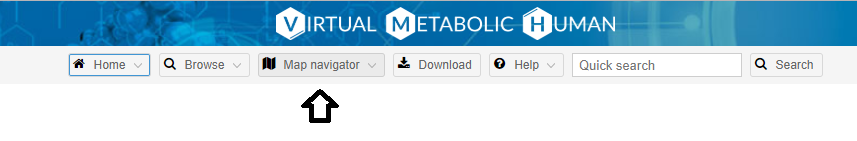

Next, click on *Overlays* and scroll down to where it says to upload your own. Login using one of the following usernames (= passwords):

- macs_student01

- macs_student02

- macs_student03

- [...]

- macs_student20

*NOTE: Team up in case of difficulties accessing the website.*

After login, click add overlay to upload the file '*Anaerobic versus aerobic_diff_overlay.txt'*. It will then look like this:

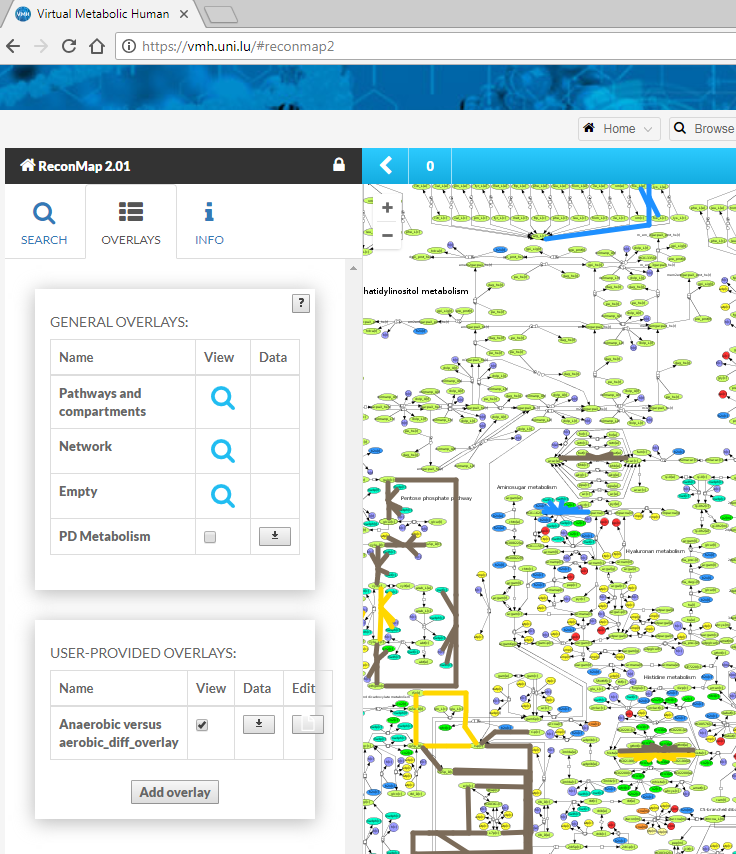

Once the visualization is done you will see three colors:

- reactions that are **more active** (in any direction!) in the anaerobic case are collored **orange**

- reactions that are **less active** (in any direction!) in the anaerobic case are collored **blue**

- reactions that **flip** (i.e. positive flux in anaerobic versus negative flux in aerobic, and vice versa) are colored **grey/taupe** 

**Questions: **

- **Can you pinpoint the lactic acid reaction we looked into earlier? How is that reaction visualized here?** (*hint: type  'lac_L[c]' in the search tab on the left)*

- **Do you see any additional interesting differences?**

...

## **~ END OF SCRIPT ~**